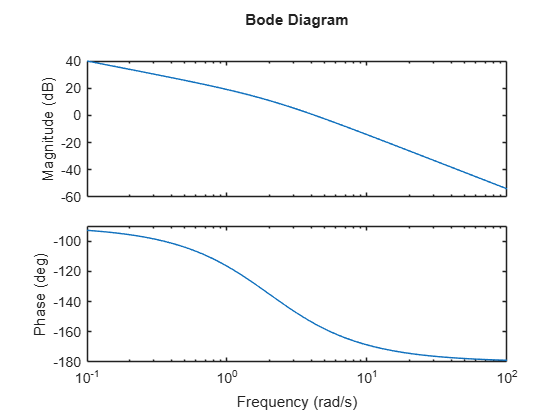

% A propria planta ja tem um integrador que anula o erro em regime permanente, visto que há um polo na origem
% erro de velocidade = 1/kv
% kv = lim s*K*1/(s*(s+2)) = 0.5*K
% para um erro de velocidade <= 0.1
% 0.1 = 1/(0.5*K)
% K = 20

% Margem de fase de ao menos 60°
% Margem de ganho de, no minimo, 12db

s = tf('s');
K = 20;
G = 1/(s*(s+2));
Gl = K*G;
bode(Gl)


% fase encontrada: -155°
% margem de fase encontrada: 25°

% % Passo 3: Margem de fase requerida - margem de fase encontrada + margem adicional
% % 60 - 25 + 7 = 42°
% % Encontrar alfa: (1 - sen(42))/(1 + sen (42))
a = (1 - sind(42))/(1 + sind(42))

a = 0.1982

 
% % Encontrar a frequencia de ponto medio
% % Wm = -20log(1/sqrt(a)) *na base 10, em db
WmMag = -20*log10(1/sqrt(a))

WmMag = -7.0283

Wm = 6.55 % rad/s

Wm = 6.5500


% 
% % Para WmMag = -7.0283, buscar no grafico de magnitude a nova frequencia de ponto medio, Wm = 6.55 rad/s
T = 1/(Wm*sqrt(a))

T = 0.3429

% 
Gc = K*(T*s+1)/(a*T*s + 1)


Gc =
 
  6.858 s + 20
  -------------
  0.06797 s + 1
 
Continuous-time transfer function.


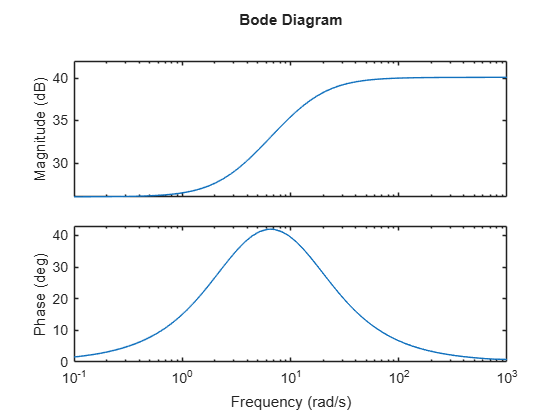

bode(Gc)

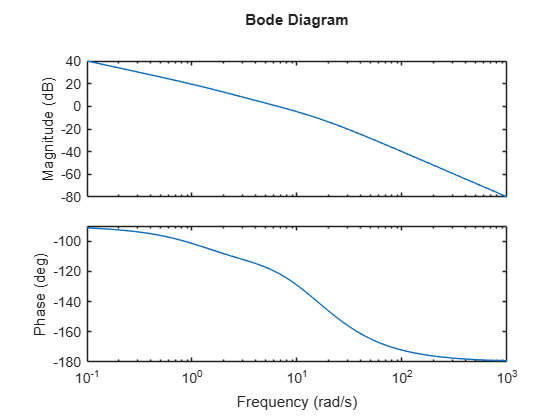

bode(Gc*G)

% 
% % A nova fase calculada (42°) corresponde a nova frequencia de cruzamento de de ganho
% 
step(feedback(G,1))
hold

Current plot held


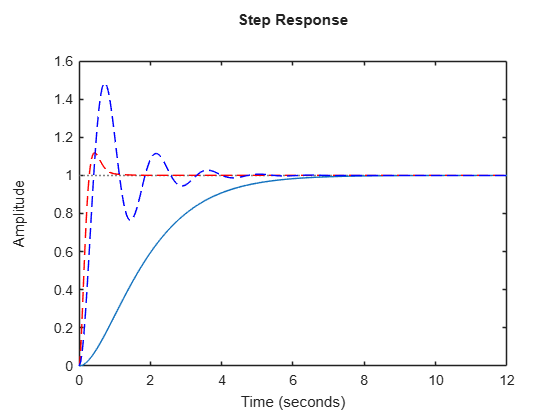

step(feedback(Gc*G,1),'--red')
step(feedback(Gl,1),'--blue')